# Projekt 2

### Zadanie 1:

clear;
disp('Zadanie 1:')

Zadanie 1:


symulacja_obiektu15y_p2(0,0,0,0,0,0)

ans = 0

SIM_LENGHT = 500;
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
Z = zeros(SIM_LENGHT,1);
STEP_MOMENT = 30;
for k=STEP_MOMENT:SIM_LENGHT
    Y(k) = symulacja_obiektu15y_p2(U(k-6), ...
        U(k-7),Z(k-3),Z(k-4), Y(k-1), Y(k-2));
end
fig = stairs(Y)

fig =   Stair with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×500 double]
              YData: [1×500 double]

  Show all properties


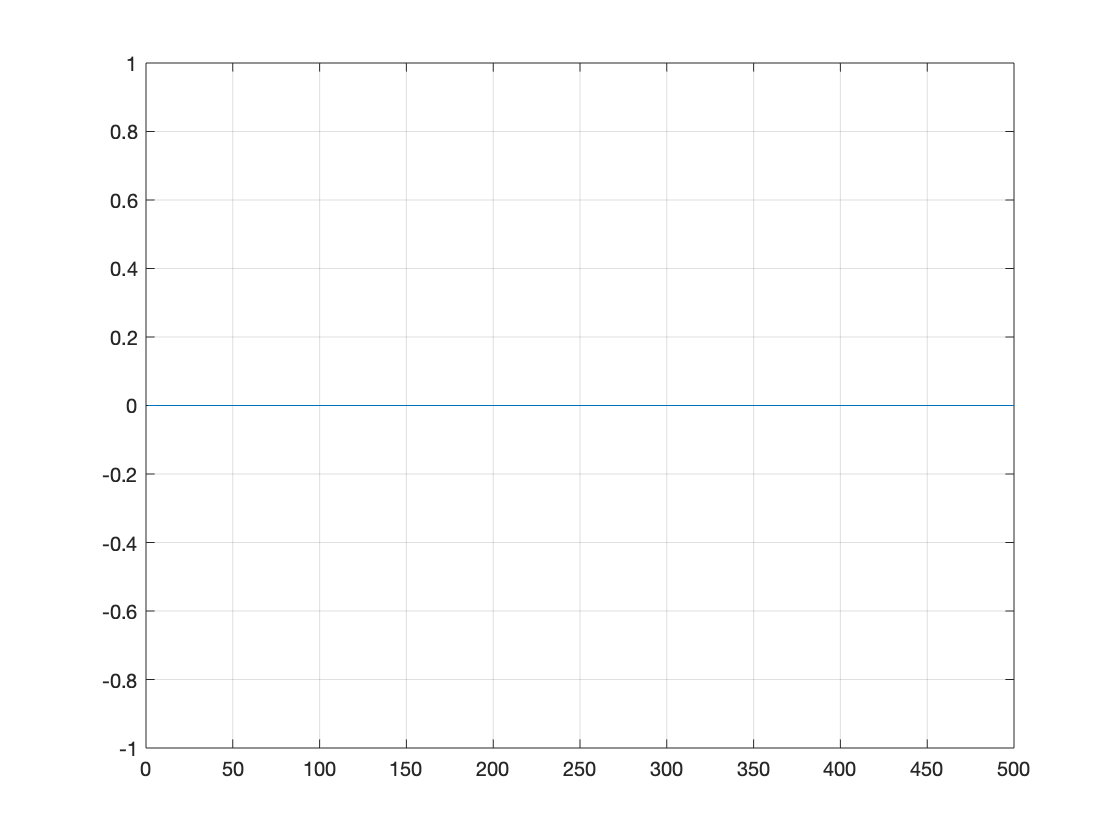

grid


writematrix([fig.XData; fig.YData]', 'txts/p2_zadanie1.txt', "Delimiter","tab")

### Zadanie 2:

clear;
disp('Zadanie 2:')

Zadanie 2:


Tor wejście wyjście

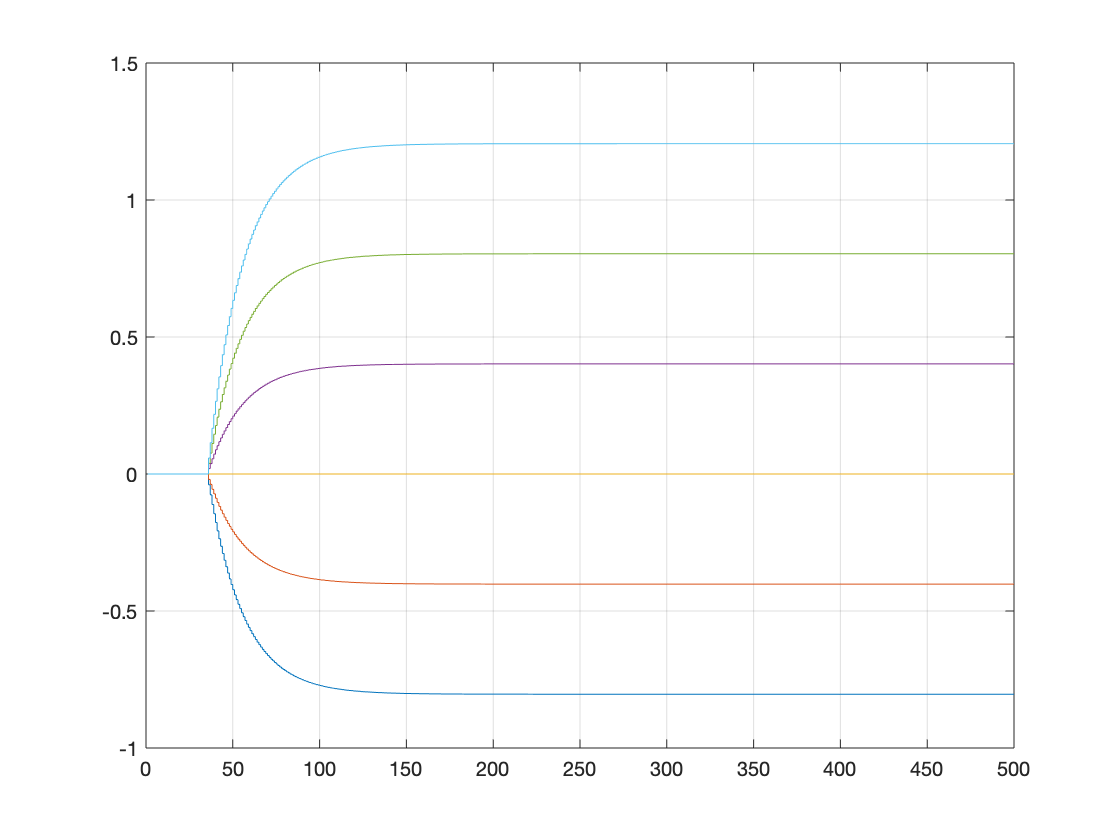

U_zad_zmiany = [-0.4,-0.2,0,0.2,0.4,0.6];
SIM_LENGHT = 500;
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
Z = zeros(SIM_LENGHT,1);

STEP_MOMENT = 30;

for p=1:length(U_zad_zmiany)
    U(STEP_MOMENT:end) = U_zad_zmiany(p);
    for k=STEP_MOMENT:SIM_LENGHT
        Y(k) = symulacja_obiektu15y_p2(U(k-6), ...
            U(k-7),Z(k-3),Z(k-4), Y(k-1), Y(k-2));
    end
    stairs(Y)
    hold on
end


grid on
hold off

Tor zakłócenie-wyjście

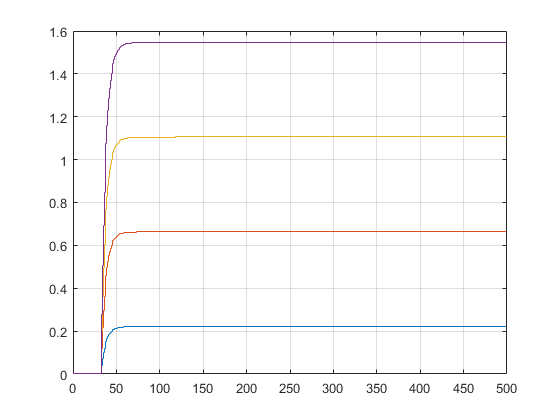

Z_zad_zmiany = [0.2, 0.6, 1, 1.4];
SIM_LENGHT = 500;
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
Z = zeros(SIM_LENGHT,1);

STEP_MOMENT = 30;

for p=1:length(Z_zad_zmiany)
    Z(STEP_MOMENT:end) = Z_zad_zmiany(p);
    for k=STEP_MOMENT:SIM_LENGHT
        Y(k) = symulacja_obiektu15y_p2(U(k-6), ...
            U(k-7),Z(k-3),Z(k-4), Y(k-1), Y(k-2));
    end
    stairs(Y)
    hold on
end


grid on
hold off

Narysować charakterystykę statyczną procesu *y*(*u,z*). Czy właściwo- ści statyczne i dynamiczne procesu są (w przybliżeniu) liniowe? Jeżeli tak, określić wzmocnienie statyczne obu torów procesu. 	 

disp('Charakterystyka statyczna:')

Charakterystyka statyczna:


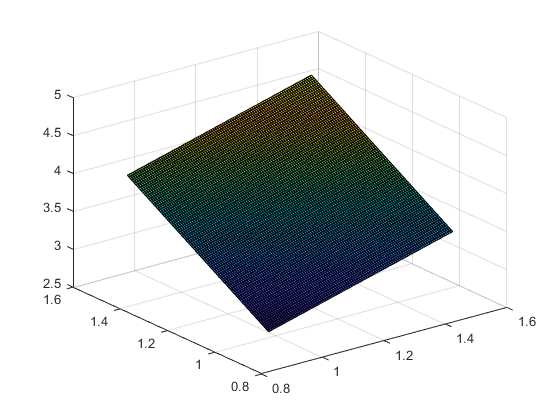

dim = 100;
Y_stat = zeros(dim,dim);

U_zad = linspace(0.9, 1.5, dim)';
Z_zad = linspace(0.9, 1.5, dim)';
X = NaN(dim*dim,3);
for i = 1:length(U_zad)
    for j = 1:length(Z_zad)
      [Y, ~, ~] = get_YUZ(U_zad(i),Z_zad(j), SIM_LENGHT, STEP_MOMENT);
      Y_stat(i,j)= Y(SIM_LENGHT);  
      X(100*(i-1)+j,:)=[1,U_zad(i),Z_zad(j)];
    end
    
end
% plot(U_zad, Y_stat)
surf(U_zad, Z_zad, Y_stat)

y = Y_stat(:);
writematrix([X(1:2:end,2),X(1:2:end,3),y(1:2:end)], 'txts/p2_zadanie2.txt', "Delimiter","tab")

Wzmocnienie statyczne to wspolczynnik kierunkowy prostej z wykresu

    b = (X'*X)\X'*y;
    gain_u = b(2)

gain_u = 1.1057

    gain_z = b(3)

gain_z = 2.0092

### Zadanie 3:

Wyznaczyć odpowiedzi skokowe obu torów wykorzystywane w algorytmie DMC, tzn. zestaw liczb *s*1*, s*2*, . . . *oraz *s*z1*, s*z2*, . . . *(przy skoku jednostkowym, odpowiednio sygnału sterującego i zakłócającego: od chwili *k *= 0 włącznie sygnał wymuszenia ma wartość 1, w przeszłości jest zerowy). Zamieścić rysunki odpowiedzi skokowych obu torów 

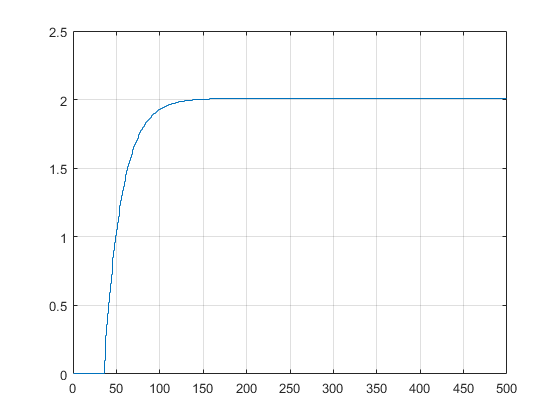

clear
SIM_LENGHT = 500;
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
Z = zeros(SIM_LENGHT,1);

STEP_MOMENT = 30;

U(STEP_MOMENT:end) = 1;
for k=STEP_MOMENT:SIM_LENGHT
    Y(k) = symulacja_obiektu15y_p2(U(k-6), ...
        U(k-7),Z(k-3),Z(k-4), Y(k-1), Y(k-2));
end
stairs(Y)
grid on

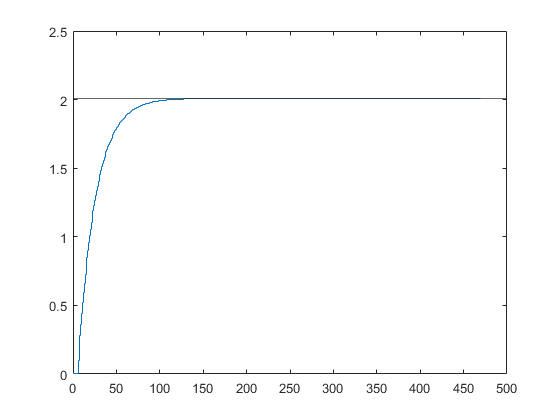

figure();
S_u = Y(STEP_MOMENT+1:end);
stairs(S_u);
yline(S_u(end));

D = find(S_u > S_u(end) - 0.0001,1,'first')

D = 205

save("data/S_u_full","S_u");
S_u = S_u(1:D);
save("data/S_u","S_u");

Tor zakłócenie-wyjście

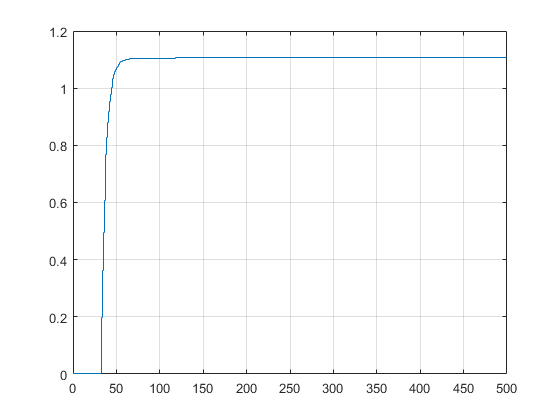

SIM_LENGHT = 500;
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
Z = zeros(SIM_LENGHT,1);

STEP_MOMENT = 30;

Z(STEP_MOMENT:end) = 1;
for k=STEP_MOMENT:SIM_LENGHT
    Y(k) = symulacja_obiektu15y_p2(U(k-6), ...
        U(k-7),Z(k-3),Z(k-4), Y(k-1), Y(k-2));
end
stairs(Y)
grid on

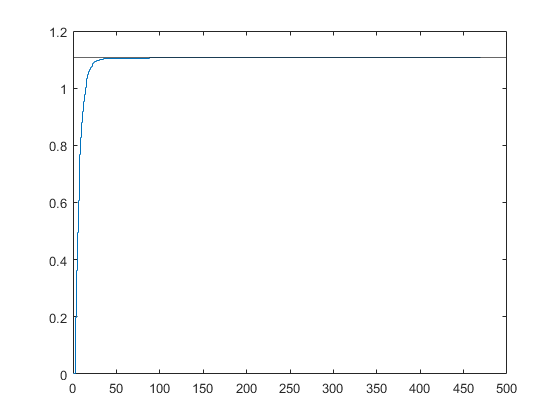

figure();
S_z = Y(STEP_MOMENT+1:end);
stairs(S_z);
yline(S_z(end));

D = find(S_z > S_z(end) - 0.0001,1,'first')

D = 95

save("data/S_z_full","S_z");
S_z = S_z(1:D);
save("data/S_z","S_z");

#### FUNKCJE:

Funkcja Piotra do wyznaczania odpowiedzi skokowych

function [Y, U, Z] = get_YUZ(U_zad,Z_zad, sim_lenght, step_moment)
Y = zeros(sim_lenght,1);
U = zeros(sim_lenght,1);
Z = zeros(sim_lenght,1);
U(step_moment:end) = U_zad;
Z(step_moment:end) = Z_zad;
for k=30:sim_lenght
    Y(k) = symulacja_obiektu15y_p2(U(k-6), ...
        U(k-7),Z(k-3),Z(k-4), Y(k-1), Y(k-2));
end
end
